[fit_YDSE, gof_YDSE] = fit(YDSE(:,1),YDSE(:,2),"smoothingspline")

fit_YDSE =      Smoothing spline:
       fit_YDSE(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

gof_YDSE = struct with fields:
           sse: 2.3359
       rsquare: 1.0000
           dfe: 39.9823
    adjrsquare: 0.9999
          rmse: 0.2417


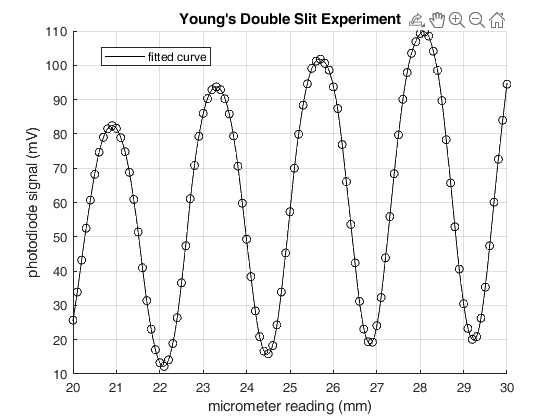

scatter(YDSE(:,1),YDSE(:,2),"k")
hold on
plot(fit_YDSE,"k")

xlim([20 30])
title("Young's Double Slit Experiment")
xlabel('micrometer reading (mm)')
ylabel('photodiode signal (mV)')
legend('Position',[0.18096,0.84365,0.19643,0.045238])
hold off

grid on

[fit_NSlit, gof_NSlit] = fit(Nslit(:,1),Nslit(:,2),"smoothingspline")

fit_NSlit =      Smoothing spline:
       fit_NSlit(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

gof_NSlit = struct with fields:
           sse: 3.6666e+03
       rsquare: 0.9919
           dfe: 27.8956
    adjrsquare: 0.9797
          rmse: 11.4648


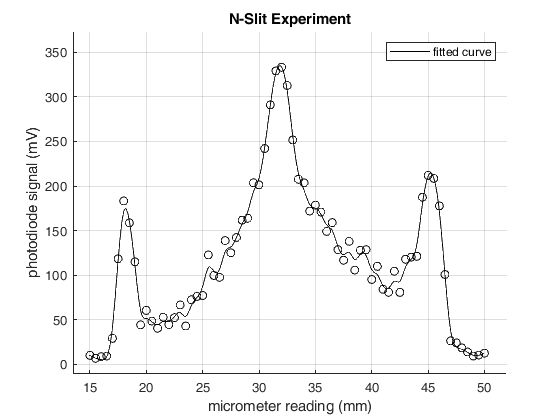

scatter(Nslit(:,1),Nslit(:,2),"k")
hold on
plot(fit_NSlit,"k")

xlim([15 50])
title("N-Slit Experiment")
xlabel('micrometer reading (mm)')
ylabel('photodiode signal (mV)')

xlim([13.5 52.0])
ylim([-11 374])
grid on